% Clear workspace, command window, and close all figures
clear;
clc;
close all;
% Increase graphics timeout
set(0, 'DefaultFigureCreateFcn', @(fig, ~)set(fig, 'CloseRequestFcn', @(src, ~)close(src)));

# State transition Parameters

% Simulation parameters
params.dt = 1;  % time step (s)
params.num_iterations = 100; % Number of time steps
params.num_vehicles = 5; % Number of vehicles 

% generate_traffic_signal_states
params.red_time = 20;   % Red light duration (s)
params.yellow_time = 3.5; % Yellow light duration (s)
params.green_time = 20; % Green light duration (s)
params.d_stop_line = 300; % Stop line position (m)

% decision making
params.D_h = 150;       % Decision distance in meters
params.T_reaction = 1.0;% Reaction time in seconds
params.p_stop = 0.5;    % Probability of stopping in the dilemma zone
params.b_max = 3.0; 
params.d_0 = 0; 

% traffic light decision model
params.T_discrete = 1.0; 
params.a = 1.0;
params.D_stop = 1;  % Assuming 1 represents D_stop
params.D_go = 2;  % Assuming 2 represents D_go
params.D_undecided = 3;

% IDM parameters
params.v_desired = 15;  % desired speed (m/s)
params.a_max = 1.0;     % maximum acceleration (m/s^2)
params.b = 1.5;         % comfortable deceleration (m/s^2)
params.s0 = 2.0;        % minimum gap (m)
params.T = 1.0;         % safe time headway (s)
params.delta = 4;       % acceleration exponent

% Acceleration noise
params.n_a = 0.1;       % Bound for uniform distribution U[-params.n_a, params.n_a]

# Measurement Parameters

% loop detectors
params.d_loop1 = 200;
params.d_loop2 = 200;
params.d_loop3 = 200;
params.dt_loop1 = 1; % s
params.dt_loop2 = 1; % s
params.dt_loop3 = 1; % s
params.accuracy_loop2 = 0.9;
%params.actual_presence = 1;

% Floating sensors
params.sigma_GPS = 5;


#  generate_traffic_signal_states

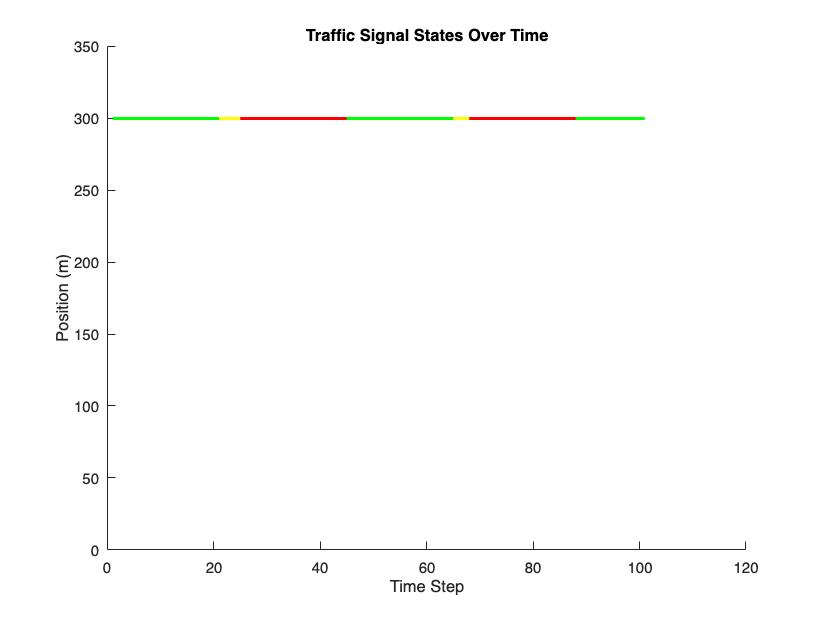

% Initialize StateTransition structure
StateTransition = state_transition();

% Generate traffic signal states
S = StateTransition.generate_traffic_signal_states(num_iterations, params);
% Plot traffic light state as a horizontal line at y = d_stop_line
figure(1);
hold on;

d_stop_line = params.d_stop_line;

for k = 1:num_iterations
    if S(k) == "red"
        stairs([k k+1], [d_stop_line d_stop_line], 'r', 'LineWidth', 2);
    elseif S(k) == "yellow"
        stairs([k k+1], [d_stop_line d_stop_line], 'y', 'LineWidth', 2);
    elseif S(k) == "green"
        stairs([k k+1], [d_stop_line d_stop_line], 'g', 'LineWidth', 2);
    end
end

xlabel('Time Step');
ylabel('Position (m)');
title('Traffic Signal States Over Time');
ylim([0 d_stop_line + 50]);
hold off;

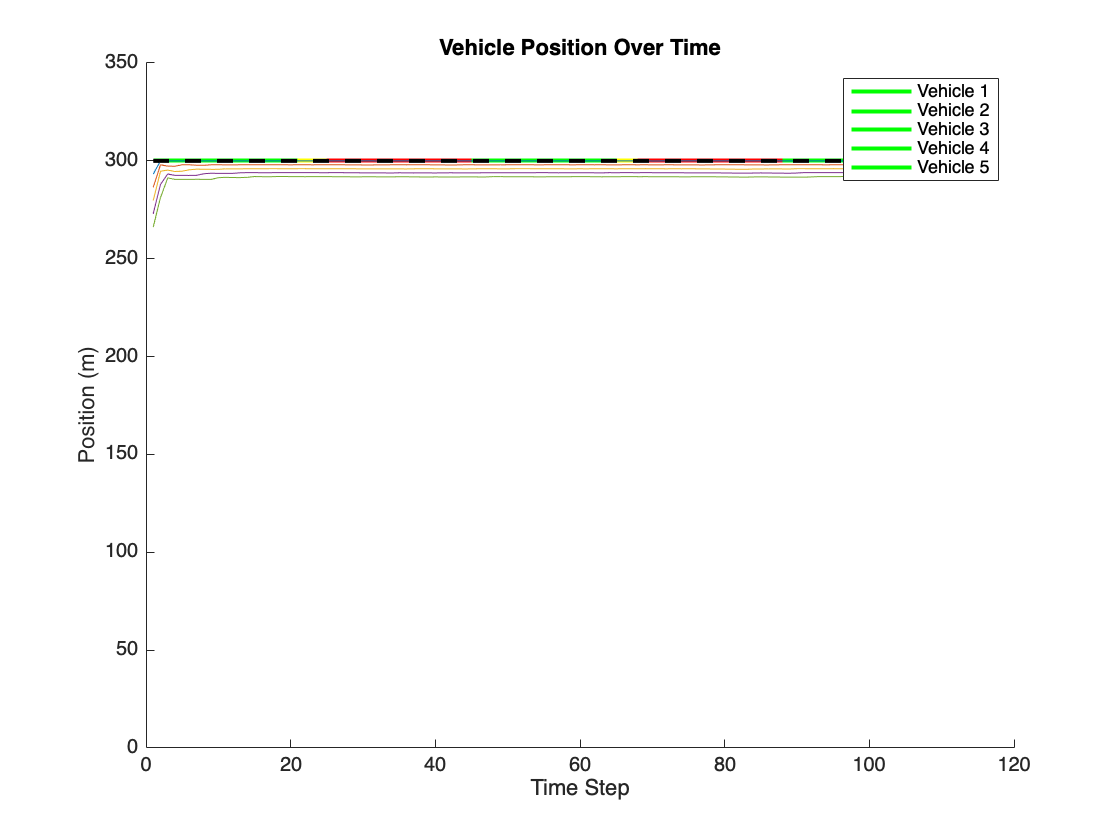

% Initialize state matrix
% state: [d, v, a, D, lane]
state = zeros(num_iterations, num_vehicles, 5);

% Initialize first state
initial_spacing = rand() * 10;  % meters
for i = 1:num_vehicles
    initial_position = max(params.d_stop_line - i * initial_spacing, 0);
    state(1, i, :) = [initial_position, params.v_desired, 0, params.D_undecided, 1];
end

% Initialize elapsed time matrix
T_elapsed = StateTransition.update_elapsed_time(num_iterations, num_vehicles, S, params);

% Main simulation loop
for k = 1:num_iterations-1
    % Calculate vehicle relations
    try
        [delta_v, s] = StateTransition.calculate_vehicle_relations(state(k, :, 1), state(k, :, 2), num_vehicles);
    catch e
        disp(['Error at iteration ', num2str(k)]);
        disp('Current state:');
        disp(squeeze(state(k, :, :)));
        rethrow(e);
    end
    
    for i = 1:num_vehicles
        % Calculate IDM acceleration
        a_IDM_next = StateTransition.intelligent_driver_model(state(k, i, 2), delta_v(i), s(i), params);
        
        % Calculate decision-based acceleration
        a_decision_next = StateTransition.traffic_light_decision_model(state(k, i, 4), state(k, i, 2), state(k, i, 1), params);
        
        % Calculate next acceleration
        a_next = StateTransition.acceleration_next(a_IDM_next, a_decision_next, params);
        
        % Calculate next state
        next_state = StateTransition.nextState(state(k, i, :), params);
        
         % Boundary condition checks
        % Make sure the vehicle does not go beyond the stop line
        if next_state(1) > params.d_stop_line
            next_state(1) = params.d_stop_line;
            next_state(2) = 0;  % speed
            next_state(3) = 0;  % acceleration
        end

        % Make sure the vehicles don’t collide
        if i > 1
            min_gap = params.s0;  % Minimum safety distance
            if next_state(1) > state(k+1, i-1, 1) - min_gap
                next_state(1) = state(k+1, i-1, 1) - min_gap;
                next_state(2) = min(next_state(2), state(k+1, i-1, 2));  % Do not exceed the speed of the vehicle in front
                next_state(3) = min(0, next_state(3));  % If too close, the acceleration is set to a negative value or 0
            end
        end

        % Update state matrix
        state(k+1, i, :) = next_state;
        state(k+1, i, 3) = a_next;  % Update acceleration
        
        % Calculate next elapsed time
        T_elapsed_next = StateTransition.calculate_T_elapsed_next(T_elapsed(k, i), S(k), S(k+1), params);
        
        % Update decision
        d_b_next = (params.yellow_time - T_elapsed_next) * next_state(2);
        d_a_next = params.T_reaction * next_state(2) + (next_state(2)^2) / (2 * params.b_max);
        D_next = StateTransition.decision_making(state(k, i, 1), next_state(1), state(k, i, 2), next_state(2), ...
                                                    S(k), S(k+1), T_elapsed(k, i), T_elapsed_next, ...
                                                    state(k, i, 4), 1, params);
        state(k+1, i, 4) = D_next;
    end
    
    % Check for invalid states
    if any(isnan(state(k+1, :))) || any(isinf(state(k+1, :)))
        disp(['Invalid state detected at iteration ', num2str(k+1)]);
        disp('Current state:');
        disp(squeeze(state(k+1, :, :)));
        error('Invalid state detected');
    end
end

% Initialize colors for plotting
%colors = lines(num_vehicles);

folder_path = '/Users/celine/Documents/MATLAB/PF-SIQE_Msc_thesis/results';


% Visualization and store the figures
% Position
figure(2);
hold on;
colors = lines(num_vehicles);
for i = 1:num_vehicles
    plot(1:num_iterations, squeeze(state(:, i, 1)), 'Color', colors(i, :));
end
plot([1 num_iterations], [params.d_stop_line params.d_stop_line], 'k--', 'LineWidth', 2);
xlabel('Time Step');
ylabel('Position (m)');
title('Vehicle Position Over Time');
legend(arrayfun(@(x) sprintf('Vehicle %d', x), 1:num_vehicles, 'UniformOutput', false));
hold off;
saveas(gcf, fullfile(folder_path, 'position_plot.fig'));

% Velocity
figure(3);
hold on;
for i = 1:num_vehicles
    plot(1:num_iterations, squeeze(state(:, i, 2)), 'Color', colors(i, :));
end
xlabel('Time Step');
ylabel('Speed (m/s)');
title('Vehicle Speed Over Time');
legend(arrayfun(@(x) sprintf('Vehicle %d', x), 1:num_vehicles, 'UniformOutput', false));
hold off;
saveas(gcf, fullfile(folder_path, 'velocity_plot.fig'));

% Acceleration
figure(4);
hold on;
for i = 1:num_vehicles
    plot(1:num_iterations, squeeze(state(:, i, 3)), 'Color', colors(i, :));
end
xlabel('Time Step');
ylabel('Acceleration (m/s^2)');
title('Vehicle Acceleration Over Time');
legend(arrayfun(@(x) sprintf('Vehicle %d', x), 1:num_vehicles, 'UniformOutput', false));
hold off;
saveas(gcf, fullfile(folder_path, 'acceleration_plot.fig'));

% Decisions
figure(5);
hold on;
for i = 1:num_vehicles
    decisions = squeeze(state(:, i, 4));
    % Map decision values to numeric values
    decision_map = containers.Map({params.D_stop, params.D_go, params.D_undecided}, {1, 2, 3});
    mapped_decisions = cellfun(@(x) decision_map(x), num2cell(decisions));
    plot(1:num_iterations, mapped_decisions, 'Color', colors(i, :));
end
xlabel('Time Step');
ylabel('Decision');
title('Vehicle Decisions Over Time');
yticks([1, 2, 3]);
yticklabels({'Stop', 'Go', 'Undecided'});
ylim([0.5, 3.5]);
legend(arrayfun(@(x) sprintf('Vehicle %d', x), 1:num_vehicles, 'UniformOutput', false));
hold off;

saveas(gcf, fullfile(folder_path, 'decision_plot.fig'));



% Display a prompt to the user asking if they want to save the figures
save_choice = input('Do you want to save the figures? (y/n): ', 's');

if strcmpi(save_choice, 'y')
    % Create a folder for saving results
    current_time = datetime(datetime("now"), 'yyyy-mm-dd_HH-MM-SS');
    folder_path = fullfile('/Users/celine/Documents/MATLAB/PF-SIQE_Msc_thesis/results', current_time);
    mkdir(folder_path);
    
    % Save figures
    for fig_num = 2:5
        figure(fig_num);
        saveas(gcf, fullfile(folder_path, sprintf('%s_plot.fig', lower(strrep(figure_titles{fig_num-1}, ' ', '_')))));
    end
    
    disp(['The figures have been saved in the folder: ' folder_path]);
else
    disp('Figures were not saved.');
end

Figures were not saved.



% Close all figures
close all;